% Start from here
addpath('./Skechers/');
load('./data/1DsktSample/1DsktSampleModel_small.mat');
B = [model.Omega_assemble.B ; model.Gamma_assemble.B]; 
d = [model.Omega_assemble.d ; model.Gamma_assemble.d];
[mB, nB] = size(B);
exact_problem.B = B;
exact_problem.d = d;

% Matrix properties
tic;
[lev_score, rank] = leverageScore(B);
levScore.lev_time = toc

levScore = 包含以下字段的 struct :
    lev_time: 0.1227


coh = max(lev_score);
if rank == nB
    fprintf('B is full rank, with coherence = %.4f.', coh);
end

B is full rank, with coherence = 0.9991.

% Generate sketching matrices
rng(3);      % random seed
s = 1; p = lev_score/sum(lev_score);
skt_coes = [2,3,4,5,6,7,8,9,10]; %[2,3,4,5,6,7];
sample = cell(2,length(skt_coes));

% Solve exact problem
tic;
exact_problem.sol = B\d;
exact_problem.time = toc;
exact_problem.sparsity = nnz(B)/(mB*nB);
exact_problem.res = norm(B*exact_problem.sol-d)

exact_problem = 包含以下字段的 struct :
           B: [25604×128 double]
           d: [25604×1 double]
         sol: [128×1 double]
        time: 0.0098
    sparsity: 0.0312
         res: 1.6288



for i = 1:length(skt_coes)
    fprintf('%d',i)
    skt_coe = skt_coes(i);
    mS = round(skt_coe * nB);
    Gaussian.S = randn(mS, mB);
    hashing.S = sHashing(s,mS,mB,'Regular'); 
    % hashing2.S = sHashing(s,mS,mB,'Variant'); 
    levScore.S = leverageScoreSampling(mS,mB,p); 
    [distlevScore.S, distlevScore.lev_time] = distributedLSS(mS,B,10);
    Sketchers = {Gaussian, hashing, levScore, distlevScore};

    for j = 1:4
        S = Sketchers{j}.S;
        tic;
        Sketchers{j}.SB = S*B; Sketchers{j}.Sd = S*d; 
        Sketchers{j}.time_sketch = toc;
    
        tic;
        Sketchers{j}.sol = Sketchers{j}.SB\Sketchers{j}.Sd;
        Sketchers{j}.time_solve = toc;
        Sketchers{j}.time_total = Sketchers{j}.time_sketch + Sketchers{j}.time_solve;
        [mm, nn] = size(Sketchers{j}.SB);
    
        Sketchers{j}.sparsity = nnz(Sketchers{j}.SB)/(mm*nn);
        Sketchers{j}.error = norm(Sketchers{j}.sol-exact_problem.sol);
        Sketchers{j}.res = norm(B*Sketchers{j}.sol-d);
    end
    
    sample_info.sketch_time_lst = cellfun(@(sk)sk.time_sketch, Sketchers);
    sample_info.solve_time_lst = cellfun(@(sk)sk.time_solve, Sketchers);
    sample_info.total_time_lst = cellfun(@(sk)sk.time_total, Sketchers);
    sample_info.sparsity_lst = cellfun(@(sk)sk.sparsity, Sketchers);
    sample_info.error_lst = cellfun(@(sk)sk.error, Sketchers);
    sample_info.res_lst = cellfun(@(sk)sk.res, Sketchers);
    sample_sol = cellfun(@(sk)sk.sol, Sketchers, 'UniformOutput', false);

    sample{1,i} = sample_info;
    sample{2,i} = sample_sol;
end

123456789


save('./data/1DsktSample/1DsktSampleResults_small.mat', 'sample');

load('./data/1DsktSample/1DsktSampleResults_small.mat');
sketch_time=[];
solve_time=[];
sparsity=[];
x_error=[];
res=[];

for i = 1:length(skt_coes)
    sketch_time=[sketch_time; sample{1,i}.sketch_time_lst];
    solve_time=[solve_time; sample{1,i}.solve_time_lst];
    sparsity=[sparsity; sample{1,i}.sparsity_lst];
    x_error=[x_error; sample{1,i}.error_lst];
    res=[res; sample{1,i}.res_lst];
end

total_time = sketch_time + solve_time;

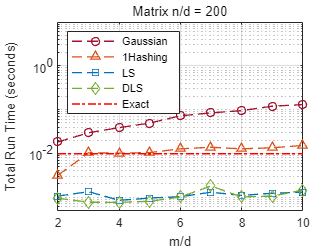

% Run time
figure;
linetype = {'--o', '--^', '--square', '--diamond'};
linecolor = {"#A2142F", "#D95319", 	"#0072BD", 	"#77AC30"};
p = semilogy(skt_coes, total_time(:,1), linetype{1}, ...
         skt_coes, total_time(:,2), linetype{2}, ...
         skt_coes, total_time(:,3), linetype{3}, ...
         skt_coes, total_time(:,4), linetype{4}, ...
         2:10, exact_problem.time*ones(1,9), '-.');
hold on 

for i = 1:4
    p(i).Color = linecolor{i};
    p(i).LineWidth = 1;
end
p(end).Color = 'r';
p(end).LineWidth = 1;
legend('Gaussian','1Hashing', 'LS', 'DLS', 'Exact',...
       'Location','northwest');
xlim([2 10]);
ylim([0.0005 10]);
grid on

xlabel("m/d");
ylabel("Total Run Time (seconds)");
title("Matrix n/d = 200"); %1000

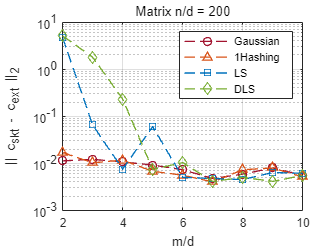


% x_error
figure;
linetype = {'--o', '--^', '--square', '--diamond'};
linecolor = {"#A2142F", "#D95319", 	"#0072BD", 	"#77AC30"};
p = semilogy(skt_coes, x_error(:,1), linetype{1}, ...
         skt_coes, x_error(:,2), linetype{2}, ...
         skt_coes, x_error(:,3), linetype{3}, ...
         skt_coes, x_error(:,4), linetype{4});
hold on 

for i = 1:4
    p(i).Color = linecolor{i};
    p(i).LineWidth = 1;
end

legend('Gaussian','1Hashing', 'LS', 'DLS',...
       'Location','northeast');
grid on

xlabel("m/d");
ylabel("|| c_{skt} - c_{ext} ||_2");
title("Matrix n/d = 200");

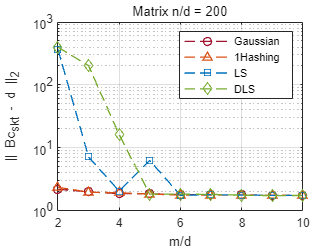


% Residual
figure;
linetype = {'--o', '--^', '--square', '--diamond'};
linecolor = {"#A2142F", "#D95319", 	"#0072BD", 	"#77AC30"};
p = semilogy(skt_coes, res(:,1), linetype{1}, ...
         skt_coes, res(:,2), linetype{2}, ...
         skt_coes, res(:,3), linetype{3}, ...
         skt_coes, res(:,4), linetype{4});
hold on 

for i = 1:4
    p(i).Color = linecolor{i};
    p(i).LineWidth = 1;
end

legend('Gaussian','1Hashing', 'LS', 'DLS',...
       'Location','northeast');
grid on

xlabel("m/d");
ylabel("|| Bc_{skt} - d ||_2");
title("Matrix n/d = 200");